**Course:                **Industrielle & Medizinische Bildverarbeitung

**Insitute:                **Salzburg University of Applied Sciences  

**Author:                 **Niko Jozic 

**Departement:       **Information Technology & System-Management

# 2.1.a

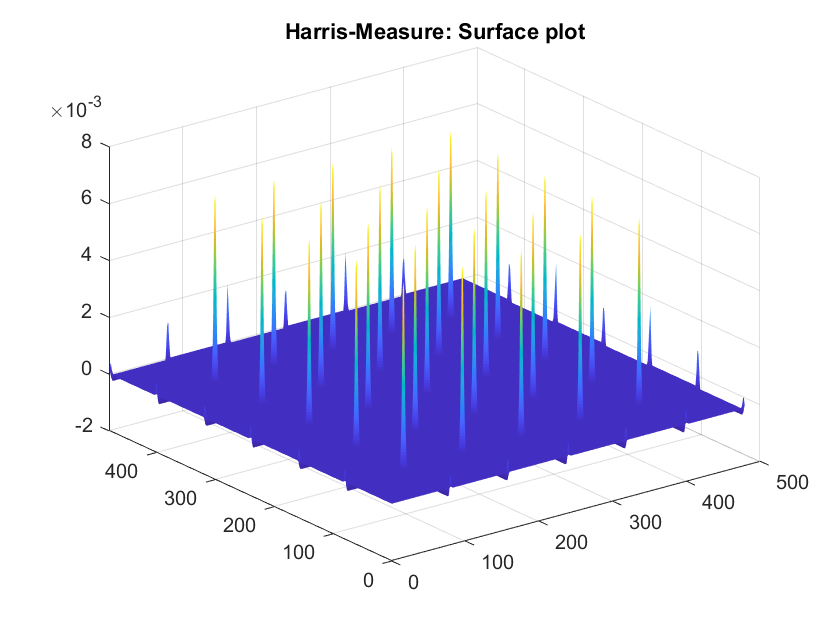

clc, clear variables, close all, format compact;

s = 1; % Sigma
ks = ceil(3*s)*2; % Kernelsize

img = checkerboard(80,3,3);
img = double(img);
img = img > 0.5;

x = -(ks-1)/2:(ks-1)/2;

gauss = exp(-x.^2/(2*s^2));
gauss = gauss ./ sum(gauss);
gauss_x = (-x./(s^2)).*gauss;
gauss_y = gauss_x';

Ix = conv2(img, gauss_x, 'same');
Iy = conv2(img, gauss_y, 'same');

g = fspecial('gaussian', ks, s);

Sx = conv2(Ix.^2,g,'same');
Sy = conv2(Iy.^2,g,'same');
Sxy = conv2(Ix.*Iy,g,'same');

k = 0.04;
Harris = ((Sx.*Sy)-(Sxy.^2))-k*((Sx+Sy).^2);

figure;
surf(Harris); shading interp;
title('Harris-Measure: Surface plot');

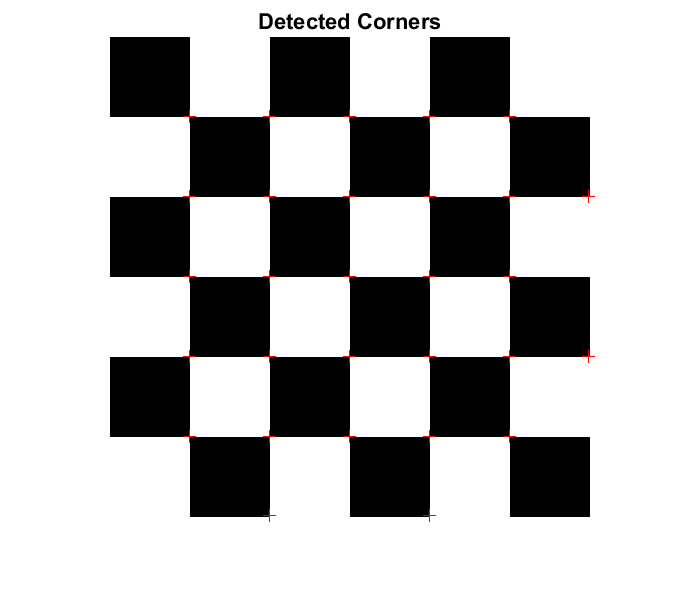


nonmaxsuppts(255 * mat2gray(Harris),1,80,img);
title('Detected Corners')

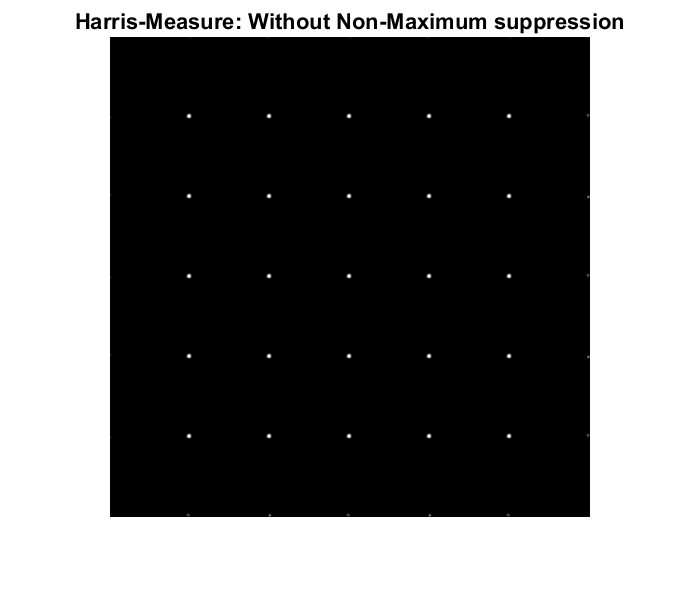


figure
imshow(255 * Harris);
title('Harris-Measure: Without Non-Maximum suppression')

# 2.1.b

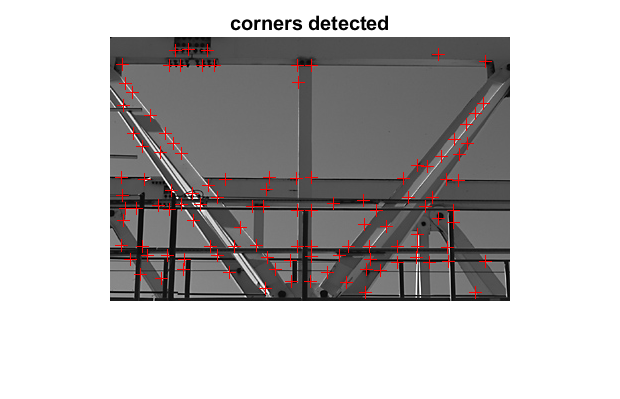

clc, clear variables, close all, format compact;

s = 1; % Sigma
ks = ceil(3*s)*2; % Kernelsize

img = imread('gantrycrane.png');
img = rgb2gray(img);
img = double(img);

x = -(ks-1)/2:(ks-1)/2;

gauss = exp(-x.^2/(2*s^2));
gauss = gauss ./ sum(gauss);
gauss_x = (-x./(s^2)).*gauss;
gauss_y = gauss_x';

Ix = conv2(img, gauss_x, 'same');
Iy = conv2(img, gauss_y, 'same');

g = fspecial('gaussian', ks, s);

Sx = conv2(Ix.^2,g,'same');
Sy = conv2(Iy.^2,g,'same');
Sxy = conv2(Ix.*Iy,g,'same');

k = 0.04;
Harris = ((Sx.*Sy)-(Sxy.^2))-k*((Sx+Sy).^2);

nonmaxsuppts(Harris,8,35,img);

# 2.1.c

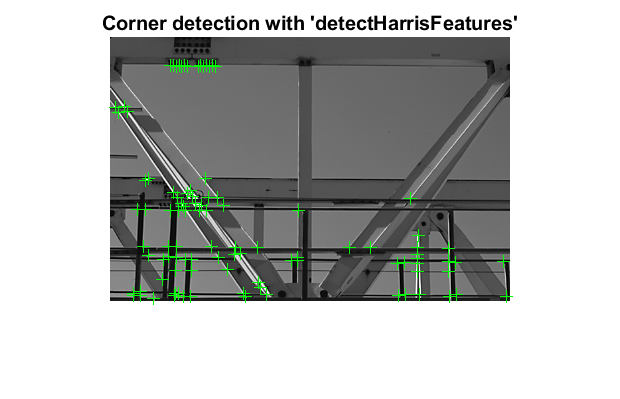

clc, clear variables, close all, format compact;

img = imread('gantrycrane.png');
img = rgb2gray(img);

points = detectHarrisFeatures(img);

imshow(img); hold on;
plot(points.selectStrongest(100));
title('Corner detection with ''detectHarrisFeatures''');

# 2.1.d

With non-maxium suppression, the gray value of a selected pixel is compared with the gray values of surrounding pixels. If the gray value of one of the surrounding pixels is more intense, the previously selected pixel is set to zero. Such maxima must be greater than the threshold value.

# 2.2.a

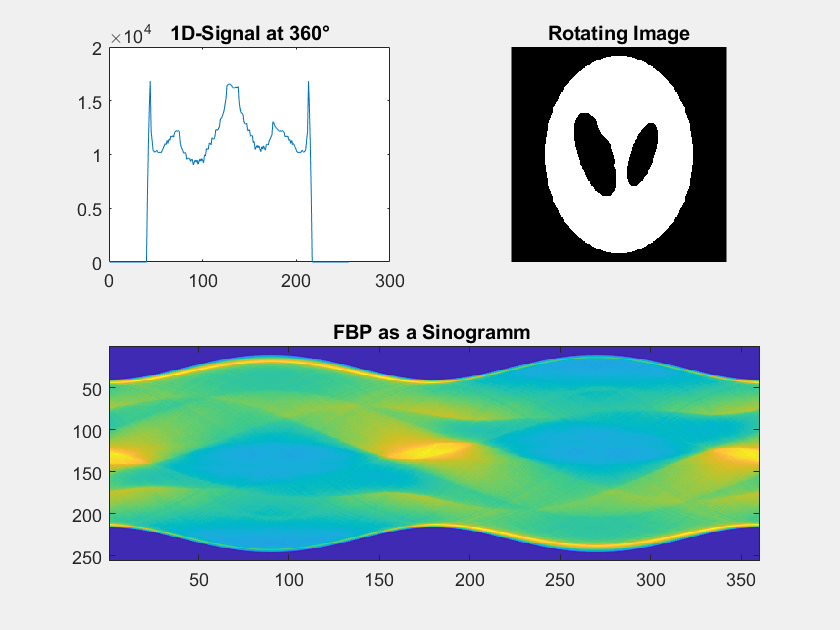

clc, clear variables, close all, format compact;

P = phantom(256);
angle = 360;

tmp_projection = Projection(P,angle);

# 2.2.b

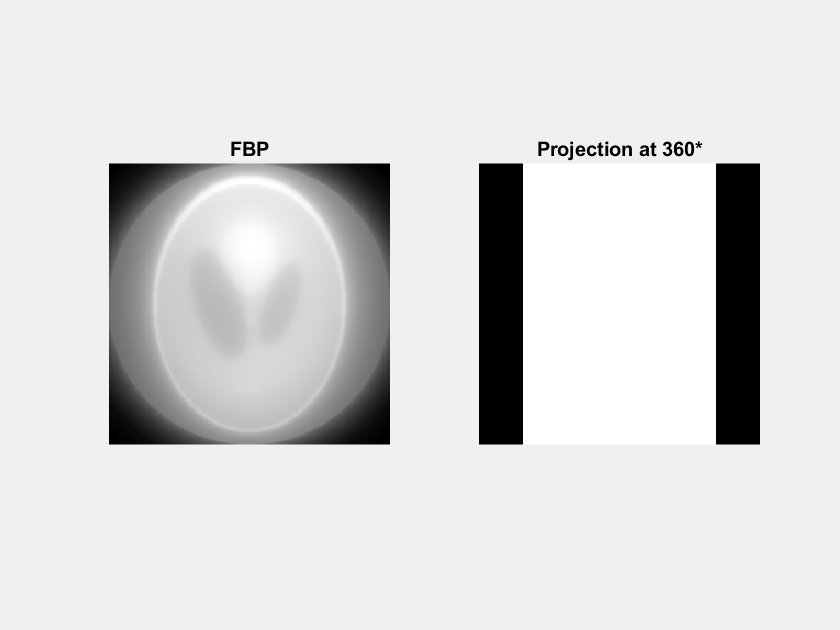

fbp(P, angle, tmp_projection);